## Missing medium on a Toy Model

Hugues Escoffier 

**Creation of a Toy Model**

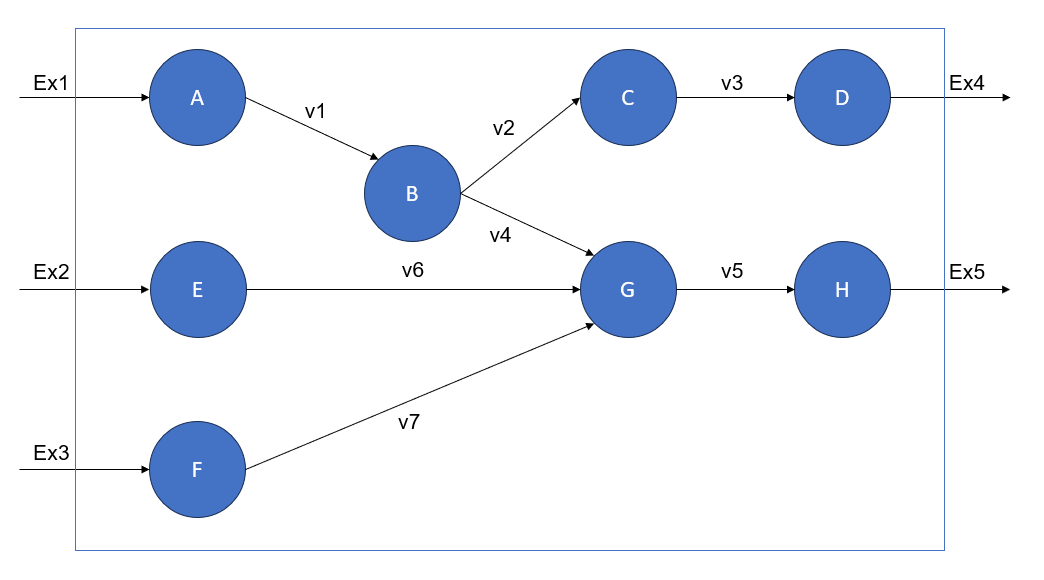

In this exercice, we want to maximize the 'Ex4' rxn. 

clear

% Create Model
ReactionFormulas = {'A -> B','B -> C', 'C -> D', 'B -> G', 'G -> H', 'E -> G', 'F -> G' ...
                    'A <=>', 'E <=>', 'F <=>', 'D ->', 'H ->'};
ReactionNames = {'v1', 'v2', 'v3', 'v4', 'v5', 'v6', 'v7', 'Ex1', 'Ex2', 'Ex3', 'Ex4', 'Ex5'};
GeneNames = {'Gene1', 'Gene2', 'Gene3', 'Gene4', 'Gene5', 'Gene6', 'Gene7', 'GeneEx1', 'GeneEx2', 'GeneEx3', 'GeneEx4', 'GeneEx5'};
model = createModel(ReactionNames, ReactionNames, ReactionFormulas,'grRuleList',GeneNames);

Adding the following Metabolites to the model:
A[c]
B[c]
C[c]
D[c]
E[c]
F[c]
G[c]
H[c]
addMultipleReactions: Adding the following reactions to the model:
v1	A[c] 	->	B[c] 
v2	B[c] 	->	C[c] 
v3	C[c] 	->	D[c] 
v4	B[c] 	->	G[c] 
v5	G[c] 	->	H[c] 
v6	E[c] 	->	G[c] 
v7	F[c] 	->	G[c] 
Ex1	A[c] 	<=>	
Ex2	E[c] 	<=>	
Ex3	F[c] 	<=>	
Ex4	D[c] 	->	
Ex5	H[c] 	->	


model.metFormulas = {'C', 'C', 'C', 'C', 'C', 'C', 'C', 'C'};

Set the objective function to 'Ex4'

model = changeObjective(model, 'Ex4');
printObjective(model);

summaryT = 1×5 table
    Coefficient    Metabolite    metID    Reaction    RxnID
    ___________    __________    _____    ________    _____

        -1            D[c]         4        Ex4        11  


#### Medium Constraints

The only metabolite present in the medium is E. 

medium = {'E[c]'}

medium = 1×1 cell array
    {'E[c]'}


[~, rxnid] = find(model.S(ismember(model.mets, medium),:));
[Ex_open] = model.rxns(rxnid)

Ex_open = 2×1 cell array
    {'v6' }
    {'Ex2'}


Ex_to_close = setdiff(model.rxns(EX),Ex_open);
medium_model = model; % Save in case of mistake
medium_model.lb(ismember(medium_model.rxns, Ex_to_close)) = 0

medium_model = struct with fields:
           rxns: {12×1 cell}
              S: [8×12 double]
             lb: [12×1 double]
             ub: [12×1 double]
              c: [12×1 double]
           mets: {8×1 cell}
              b: [8×1 double]
          rules: {12×1 cell}
          genes: {12×1 cell}
      osenseStr: 'max'
         csense: [8×1 char]
     rxnGeneMat: [12×12 double]
       metNames: {8×1 cell}
     subSystems: {12×1 cell}
        grRules: {12×1 cell}
       rxnNames: {12×1 cell}
    metFormulas: {'C'  'C'  'C'  'C'  'C'  'C'  'C'  'C'}


% Create a consistent model constrained by the metabolites present in the model 
A = fastcc_4_rfastcormics(medium_model, 1e-4, 0);

Optimal solution found.

Elapsed time is 0.030219 seconds.


medium_constrained_consistent_model = removeRxns(medium_model,medium_model.rxns(setdiff(1:numel(medium_model.rxns), A)))

medium_constrained_consistent_model = struct with fields:
           rxns: {4×1 cell}
              S: [3×4 double]
             lb: [4×1 double]
             ub: [4×1 double]
              c: [4×1 double]
           mets: {3×1 cell}
              b: [3×1 double]
          rules: {4×1 cell}
          genes: {12×1 cell}
      osenseStr: 'max'
         csense: [3×1 char]
     rxnGeneMat: [4×12 double]
       metNames: {3×1 cell}
     subSystems: {4×1 cell}
        grRules: {4×1 cell}
       rxnNames: {4×1 cell}
    metFormulas: {'C'  'C'  'C'  'C'  'C'  'C'  'C'  'C'}


Display the objective function 

printObjective(medium_constrained_consistent_model)


ans =

  0×1 empty cell array



As you can see, the objective function was lost when the model was medium constrained because the medium did not contain the necessary metabolite. 

In this example we'll see how to identify the missing metabolite so that we can add it to the medium and carry out the optimisation we want. 

% Find the medium exchange reactions 
exRxns = model.rxns(findExcRxns(model)); % All exchanges reactions
all_medium_rxns = findRxnsFromMets(model, medium); % All medium rxns
exToKeep = intersect(exRxns, all_medium_rxns); % Medium exchange reactions (MER)

[model_cons] = constrain_model_rFASTCORMICS(model, medium, [], 'Ex4', 'Ex4'); 
exToRemove = model.rxns(model.lb ~= model_cons.lb | model.ub ~= model_cons.ub); % Ex rxns that are close when we do the medium constrained

% Find the missing exchange rxns 
C = find(ismember(model.rxns, 'Ex4')); % Index of the objective rxn 
allowedInputRxns = find(ismember(model.rxns, exToKeep)); % Indices of MER

A = fastcore_4_rfastcormics(C, model, 1e-4, allowedInputRxns); 

Optimal solution found.



rxns_to_keep = model.rxns(A) % List of the minimal rxns to keep the objective function 

rxns_to_keep = 5×1 cell array
    {'v1' }
    {'v2' }
    {'v3' }
    {'Ex1'}
    {'Ex4'}


missing_needed_rxns = intersect(exToRemove, model.rxns(A));
missing_needed_metabolites = findMetsFromRxns(model, missing_needed_rxns); % Find missing metabolites from rxns 
medium_with_missing_metabolites = cat(1, medium, missing_needed_metabolites);

The analysis can now be re-run using the corrected medium 

[EX] = findExcRxns(model); % Find all exchange reactions
[~, rxnid] = find(model.S(ismember(model.mets, medium_with_missing_metabolites),:)); % New medium 
[Ex_open] = model.rxns(rxnid)

Ex_open = 4×1 cell array
    {'v1' }
    {'v6' }
    {'Ex1'}
    {'Ex2'}


Ex_to_close = setdiff(model.rxns(EX),Ex_open);
medium_model = model; % Save in case of mistake
medium_model.lb(ismember(medium_model.rxns, Ex_to_close)) = 0

medium_model = struct with fields:
           rxns: {12×1 cell}
              S: [8×12 double]
             lb: [12×1 double]
             ub: [12×1 double]
              c: [12×1 double]
           mets: {8×1 cell}
              b: [8×1 double]
          rules: {12×1 cell}
          genes: {12×1 cell}
      osenseStr: 'max'
         csense: [8×1 char]
     rxnGeneMat: [12×12 double]
       metNames: {8×1 cell}
     subSystems: {12×1 cell}
        grRules: {12×1 cell}
       rxnNames: {12×1 cell}
    metFormulas: {'C'  'C'  'C'  'C'  'C'  'C'  'C'  'C'}


% Create a consistent model constrained by the metabolites present in the model 
A = fastcc_4_rfastcormics(medium_model, 1e-4, 0);

Optimal solution found.

Elapsed time is 0.011768 seconds.


medium_constrained_consistent_model = removeRxns(medium_model, medium_model.rxns(setdiff(1:numel(medium_model.rxns), A)))

medium_constrained_consistent_model = struct with fields:
           rxns: {10×1 cell}
              S: [7×10 double]
             lb: [10×1 double]
             ub: [10×1 double]
              c: [10×1 double]
           mets: {7×1 cell}
              b: [7×1 double]
          rules: {10×1 cell}
          genes: {12×1 cell}
      osenseStr: 'max'
         csense: [7×1 char]
     rxnGeneMat: [10×12 double]
       metNames: {7×1 cell}
     subSystems: {10×1 cell}
        grRules: {10×1 cell}
       rxnNames: {10×1 cell}
    metFormulas: {'C'  'C'  'C'  'C'  'C'  'C'  'C'  'C'}


printObjective(medium_constrained_consistent_model)

summaryT = 1×5 table
    Coefficient    Metabolite    metID    Reaction    RxnID
    ___________    __________    _____    ________    _____

        -1            D[c]         4        Ex4         9  


ans = 1×1 cell array
    {'Ex4'}
